# MSS - module 2: solution exercise 2

# Written exam 2025/08/28

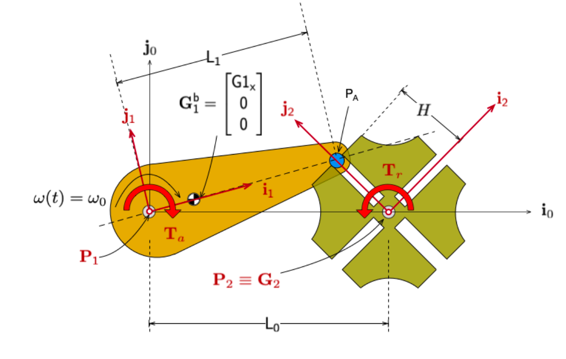

Compute the 

- Draw the LG and the normal tree of the system

- derive the kinematic constraint equations using the recursive formulation (i.e. loop equations)

- derive the expression of conditions of pin PA engaged with wheel.

- derive the expression of the point G1 and its velocity and acceleration.

- derive the node equations and the equations of motion using the Neutown Euler approach

- Optional include the friction in the contact bewteen the slot and the pin PA.


clear all
clear;
addpath('../MBsLib_v2_1/')

## Linear Graph and normal tree

The LG shows that the Multibody system is made of 2 revolute joint, one cam joint.

The cam joint is the cut joint. LG shows also the points of application of external torques.

NB: please note that the edges of body G1 and  body G2 are not displaed in the LG.

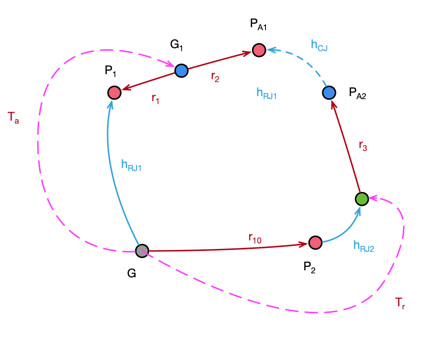

The normal tree contains the joint: {revolute joint RJ1, revolute joint RJ2}. The corresponding branch coordinates are 


$$\mathbf{q}=\{\theta_1(t),\theta_2(t)\}$$


The cam joint is the cut joint where loop equation is defined.

**Note: the positions of the contact point of the cam joint along one of the axis of 1 of the four slots. In this case we consider the pin in contact with the slot along the j2 axis as in the piscture. The variable s(t) which defines the position along the slot is not strictly necessary to be defined. However in this case since we have to define the conditon of ingagement we include it in the variable list.** 

Definition of variables and parameters

syms  theta_1(t) theta_2(t) theta_3(t) s(t)

% Parameters
syms L_0 L_1 H G_x1

We next define the joint matrices and the vectors (edges) of the T-graph

% Transformation matrix of revolute joint 1
R1 = rotate("Z",theta_1(t))

$$R1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Revolute joint 1 translation vector
r_RJ1 = R1(:,4)

$$r\_RJ1 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 1 \end{array}\right)$$


% Vector r1 in world frame 
r1 = R1*[-G_x1;0;0;0];

% Vector r2 in world frame 
r2 = R1*[L_1-G_x1;0;0;0];

% Vector r10 in world frame 
r10 = [L_0;0;0;0];

% Rotation matrix of Revolute joints
R2 = rotate("Z",theta_2(t))

$$R2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{2}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Revolute joint 1 translation vector
r_RJ2 = R2(:,4)

$$r\_RJ2 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 1 \end{array}\right)$$

% Vector r3 in world frame of point PB
r3 = R2*[0;H;0;0];

Cam joint transformation matrix

T3 = translate([0,s(t),0])*rotate("Z",theta_3(t))

$$T3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\left(t\right)\right) & -\sin\left(\theta_{3}\left(t\right)\right) & 0 & 0\\ \sin\left(\theta_{3}\left(t\right)\right) & \cos\left(\theta_{3}\left(t\right)\right) & 0 & s\left(t\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% vector of cam jojnt translation in world frame
r_cj = R2*[T3(1:3,4);0]

$$r\_cj = \left(\begin{array}{c} -\sin\left(\theta_{2}\left(t\right)\right)\,s\left(t\right)\\ \cos\left(\theta_{2}\left(t\right)\right)\,s\left(t\right)\\ 0\\ 0 \end{array}\right)$$

### Loop equations

% Vector between point P2 and PB
rcj1 = r_RJ1-r1+r2-(r10+r_RJ2+r3)

$$rcj1 = \left(\begin{array}{c} H\,\sin\left(\theta_{2}\left(t\right)\right)-L_{0}+G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)-\cos\left(\theta_{1}\left(t\right)\right)\,\left(G_{\mathrm{x1}}-L_{1}\right)\\ G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)-\sin\left(\theta_{1}\left(t\right)\right)\,\left(G_{\mathrm{x1}}-L_{1}\right)-H\,\cos\left(\theta_{2}\left(t\right)\right)\\ 0\\ 0 \end{array}\right)$$

We project the vector in the constraint **reaction space**. That is in the direction of unit vector i2 where the relative motion cannot occur. 

% Projection in reaction space
i2 = R2(:,1); % get_unit_vector("X",R2)
loop_eq1 = simplify(rcj1.'*i2 ) == 0

$$loop\_eq1 = L_{1}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-L_{0}\,\cos\left(\theta_{2}\left(t\right)\right)=0$$

The projection in the motion space (instead), defines the coordiates of the position of the pin point PA in the y-axis of the body. In this case we do not use it.

% Vector between point P1 and PA
% Projection in reaction space
j2 = R2(:,2); % get_unit_vector("Y",R2)
loop_eq2 = s(t) == simplify(rcj1.'*j2) 

$$loop\_eq2 = s\left(t\right)=L_{0}\,\sin\left(\theta_{2}\left(t\right)\right)-H+L_{1}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)$$

**NOTE: When s(t) > 0: not in engaged. When s(t) < 0: engaged**

### Positions of points

% Velocity
syms theta_dot1(t) theta_dot2(t)

P0 = [0;0;0;1]; % Origin

% Position of centre of mass
G1 = P0+r_RJ1-r1;
% veclocity
VG1 = subs( diff(G1,t),[diff(theta_1(t),t)],[theta_dot1(t)])

$$VG1 = \left(\begin{array}{c} -G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\\ G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

% Acceleration
AG1 = diff(VG1,t)

$$AG1 = \left(\begin{array}{c} -G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)-G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)-G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ 0\\ 0 \end{array}\right)$$

% Position of centre of mass
G2 = P0+r10+r_RJ2;
% veclocity
VG2 = subs( diff(G2,t),[diff(theta_2(t),t)],[theta_dot2(t)])

$$VG2 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

% Acceleration
AG2 = diff(VG2,t)

$$AG2 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

**Points**

P1 = P0+r_RJ1; % in world coords
P2 = P0+r10; % in world coords

PA1 = P0+r_RJ1-r1+r2; % in world coords
PA2 = P0+r10+r_RJ2+r3+r_cj; % in world coords

% Vector between G2 and PA and PB (Please not that PA and PB are projected in body coords)

VG1PA = simplify(inv_frame(R1)*(PA1-G1)) % in body frame

$$VG1PA = \left(\begin{array}{c} L_{1}-G_{\mathrm{x1}}\\ 0\\ 0\\ 0 \end{array}\right)$$

VG1P1 = simplify(inv_frame(R1)*(P1-G1))  % in body frame

$$VG1P1 = \left(\begin{array}{c} -G_{\mathrm{x1}}\\ 0\\ 0\\ 0 \end{array}\right)$$

VG2PA = simplify(inv_frame(R2)*(PA2-G2))  % in body frame

$$VG2PA = \left(\begin{array}{c} 0\\ H+s\left(t\right)\\ 0\\ 0 \end{array}\right)$$

VG2P2 = inv_frame(R2)*(P2-G2)  % in body frame

$$VG2P2 = \left(\begin{array}{c} 0\\ 0\\ 0\\ -1 \end{array}\right)$$

## Newton Euler Equations

% definition of force/torque components
syms N(t)              % reaction Cam. Joint
syms RJ1_x(t) RJ1_y(t) % reaction Rev. Joint 1
syms RJ2_x(t) RJ2_y(t) % reaction Rev. Joint 2

syms T_a(t) T_r(t) % external torques
syms m1 Iz1 m2 Iz2


### Body 1 balance: (i.e. Node balance)

% Joint reaction forces in world coordinates
F_RJ1 = [RJ1_x(t);RJ1_y(t);0;0]; % rev. joint 1
F_CJ1 = R2*[-N(t);0;0;0]; % cam joint: NOTE: positive acting on body 2

FW1 = [0;0;0;0]; % weight

TA = [0;0;T_a(t);0]; % actuation torque

#### **Translation: node balance (in world frame)**

FB1 = +F_RJ1+F_CJ1+FW1

$$FB1 = \left(\begin{array}{c} {\mathrm{RJ}}_{1,x}\left(t\right)-\cos\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ {\mathrm{RJ}}_{1,y}\left(t\right)-\sin\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ 0\\ 0 \end{array}\right)$$

#### **Rotation: node balance (in body frame)**

TB1 = cross_prod2(VG1P1,inv_frame(R1)*F_RJ1)+cross_prod2(VG1PA,inv_frame(R1)*F_CJ1)+TA

$$TB1 = \left(\begin{array}{c} 0\\ 0\\ T_{a}\left(t\right)-\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,N\left(t\right)\,\left(G_{\mathrm{x1}}-L_{1}\right)-G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{RJ}}_{1,y}\left(t\right)+G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{RJ}}_{1,x}\left(t\right)\\ 0 \end{array}\right)$$

#### Constitutive equations (i.e. Newton Euler equations)

Newton Euler 1st body

% Newton equations
eq_N1 = m1*AG1 == FB1;
%Euler equations
eq_E1 = Iz1*diff(theta_dot1(t),t) == TB1(3)

$$eq\_E1 = {\mathrm{Iz}}_{1}\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)=T_{a}\left(t\right)-\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,N\left(t\right)\,\left(G_{\mathrm{x1}}-L_{1}\right)-G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{RJ}}_{1,y}\left(t\right)+G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{RJ}}_{1,x}\left(t\right)$$

### Body 2 balance: (i.e. Node balance)

% Joint reaction forces in world coordinates
F_RJ2 = [RJ2_x(t);RJ2_y(t);0;0]; % rev. joint 1
F_CJ2 = R2*[N(t);0;0;0]; % cam joint: NOTE: positive acting on body 2

FW2 = [0;0;0;0]; % weight

TR = [0;0;T_r(t);0]; % actuation torque

#### **Translation: node balance (in world frame)**

FB2 = +F_RJ2+F_CJ2+FW2

$$FB2 = \left(\begin{array}{c} {\mathrm{RJ}}_{2,x}\left(t\right)+\cos\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ {\mathrm{RJ}}_{2,y}\left(t\right)+\sin\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ 0\\ 0 \end{array}\right)$$

#### **Rotation: node balance (in body frame)**

TB2 = cross_prod2(VG2P2,inv_frame(R2)*F_RJ2)+cross_prod2(VG2PA,inv_frame(R2)*F_CJ2)+TR

$$TB2 = \left(\begin{array}{c} 0\\ 0\\ T_{r}\left(t\right)-N\left(t\right)\,\left(H+s\left(t\right)\right)\\ 0 \end{array}\right)$$

#### Constitutive equations (i.e. Newton Euler equations)

Newton Euler 2nd body

% Newton equations
eq_N2 = m2*AG2 == FB2

$$eq\_N2 = \left(\begin{array}{c} 0={\mathrm{RJ}}_{2,x}\left(t\right)+\cos\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ 0={\mathrm{RJ}}_{2,y}\left(t\right)+\sin\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ 0=0\\ 0=0 \end{array}\right)$$

%Euler equations
eq_E2 = Iz2*diff(theta_dot2(t),t) == TB2(3)

$$eq\_E2 = {\mathrm{Iz}}_{2}\,\frac{\partial }{\partial t}\theta_{\mathrm{dot2}}\left(t\right)=T_{r}\left(t\right)-N\left(t\right)\,\left(H+s\left(t\right)\right)$$

## Full set of equations of motions

dae_eqns = [eq_N1(1:2);eq_N2(1:2);...
            eq_E1;eq_E2; ...
            loop_eq1
             ]

$$dae\_eqns = \begin{array}{l} \left(\begin{array}{c} -m_{1}\,\left(G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)+G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)={\mathrm{RJ}}_{1,x}\left(t\right)-\sigma_{2}\\ m_{1}\,\left(G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)-G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)={\mathrm{RJ}}_{1,y}\left(t\right)-\sigma_{1}\\ 0={\mathrm{RJ}}_{2,x}\left(t\right)+\sigma_{2}\\ 0={\mathrm{RJ}}_{2,y}\left(t\right)+\sigma_{1}\\ {\mathrm{Iz}}_{1}\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)=T_{a}\left(t\right)-\sin\left(\sigma_{3}\right)\,N\left(t\right)\,\left(G_{\mathrm{x1}}-L_{1}\right)-G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\mathrm{RJ}}_{1,y}\left(t\right)+G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\mathrm{RJ}}_{1,x}\left(t\right)\\ {\mathrm{Iz}}_{2}\,\frac{\partial }{\partial t}\theta_{\mathrm{dot2}}\left(t\right)=T_{r}\left(t\right)-N\left(t\right)\,\left(H+s\left(t\right)\right)\\ L_{1}\,\cos\left(\sigma_{3}\right)-L_{0}\,\cos\left(\theta_{2}\left(t\right)\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ \sigma_{2}=\cos\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ \sigma_{3}=\theta_{1}\left(t\right)-\theta_{2}\left(t\right) \end{array}$$

The first 4 equations can be used to compute the revolute joint reaction forces.

r_vars = [ RJ1_x(t) RJ1_y(t) RJ2_x(t) RJ2_y(t) ]

$$r\_vars = \left(\begin{array}{cccc} {\mathrm{RJ}}_{1,x}\left(t\right) & {\mathrm{RJ}}_{1,y}\left(t\right) & {\mathrm{RJ}}_{2,x}\left(t\right) & {\mathrm{RJ}}_{2,y}\left(t\right) \end{array}\right)$$

% Symbolic vector for revolute joint reaction forces' components
GenR = sym("R",[1,4]);
tmp = subs( dae_eqns(1:4,1),num2cell(r_vars),num2cell(GenR));
tmp_sol = solve(tmp,GenR);
sol_R = r_vars.'== [tmp_sol.R1;tmp_sol.R2;tmp_sol.R3;tmp_sol.R4]

$$sol\_R = \begin{array}{l} \left(\begin{array}{c} {\mathrm{RJ}}_{1,x}\left(t\right)=\sigma_{2}-m_{1}\,\left(G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)+G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)\\ {\mathrm{RJ}}_{1,y}\left(t\right)=\sigma_{1}+m_{1}\,\left(G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)-G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)\\ {\mathrm{RJ}}_{2,x}\left(t\right)=-\sigma_{2}\\ {\mathrm{RJ}}_{2,y}\left(t\right)=-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)\\ \sigma_{2}=\cos\left(\theta_{2}\left(t\right)\right)\,N\left(t\right) \end{array}$$

The remainng DAE equations are used to compute $\theta1, \theta2, N$ given $T_a, T_r$ (i.e. direct dynamics):

(subs( dae_eqns(5:end,1),num2cell(lhs(sol_R)),num2cell(rhs(sol_R))))

$$ans = \begin{array}{l} \left(\begin{array}{c} {\mathrm{Iz}}_{1}\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)=T_{a}\left(t\right)-G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\left(\sin\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)+m_{1}\,\left(G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)-G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)\right)+G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\left(\cos\left(\theta_{2}\left(t\right)\right)\,N\left(t\right)-m_{1}\,\left(G_{\mathrm{x1}}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{dot1}}\left(t\right)+G_{\mathrm{x1}}\,\cos\left(\theta_{1}\left(t\right)\right)\,\theta_{\mathrm{dot1}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)\right)-\sin\left(\sigma_{1}\right)\,N\left(t\right)\,\left(G_{\mathrm{x1}}-L_{1}\right)\\ {\mathrm{Iz}}_{2}\,\frac{\partial }{\partial t}\theta_{\mathrm{dot2}}\left(t\right)=T_{r}\left(t\right)-N\left(t\right)\,\left(H+s\left(t\right)\right)\\ L_{1}\,\cos\left(\sigma_{1}\right)-L_{0}\,\cos\left(\theta_{2}\left(t\right)\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}\left(t\right)-\theta_{2}\left(t\right) \end{array}$$